## (a)

N=10000;
p1=0.002;
p2=0.005;
pa=0.01;
n=8;
k=0;

lancamentos1 = rand(n, N) < p1;
sucessos1 = sum(lancamentos1) == k;
P1 = sum(sucessos1) / N;

lancamentos2 = rand(n, N) < p2;
sucessos2 = sum(lancamentos2) == k;
P2 = sum(sucessos2) / N;

lancamentosA = rand(n, N) < pa;
sucessosA = sum(lancamentosA) == k;
PA = sum(sucessosA) / N;

prob = 1-((1-P1)+(1-P2)+(1-PA))

prob = 0.8661

## (b)

p1=0.002;
p2=0.005;
pa=0.01;
n=8;

prob = (1-p1)^n * (1-p2)^n * (1-pa)^n

prob = 0.8724

## (c)

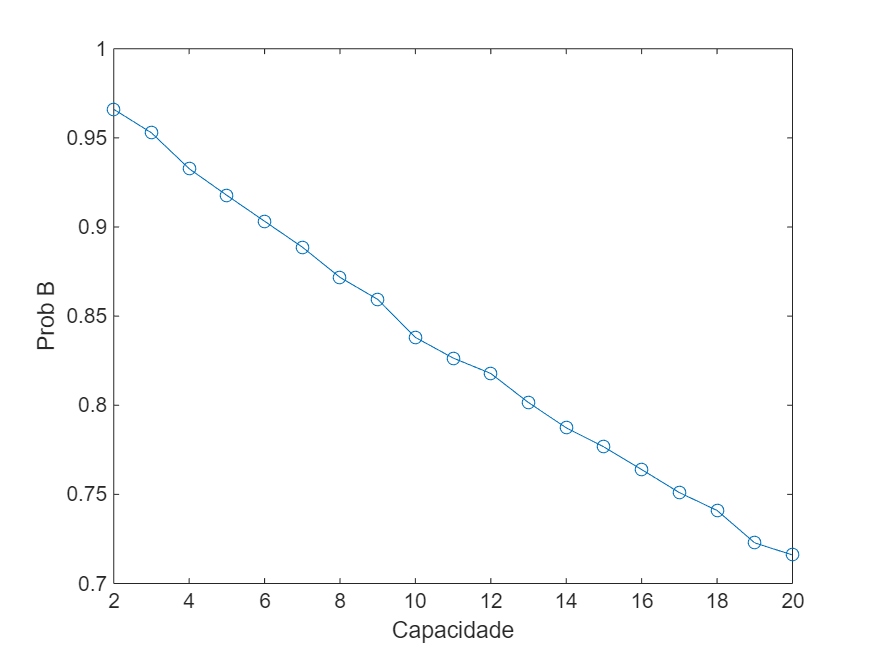

N=10000;
p1=0.002;
p2=0.005;
pa=0.01;
nN=2:20;
k=0;

P = zeros(1,length(nN));

for i = 1:length(nN)
    n = nN(i);

    lancamentos1 = rand(n, N) < p1;
    sucessos1 = sum(lancamentos1) == k;
    P1 = sum(sucessos1) / N;

    lancamentos2 = rand(n, N) < p2;
    sucessos2 = sum(lancamentos2) == k;
    P2 = sum(sucessos2) / N;

    lancamentosA = rand(n, N) < pa;
    sucessosA = sum(lancamentosA) == k;
    PA = sum(sucessosA) / N;

    P(i)=P1*P2*PA;
end
figure;
plot(nN,P,'-o');
xlabel("Capacidade");
ylabel("Prob B");

## (d)

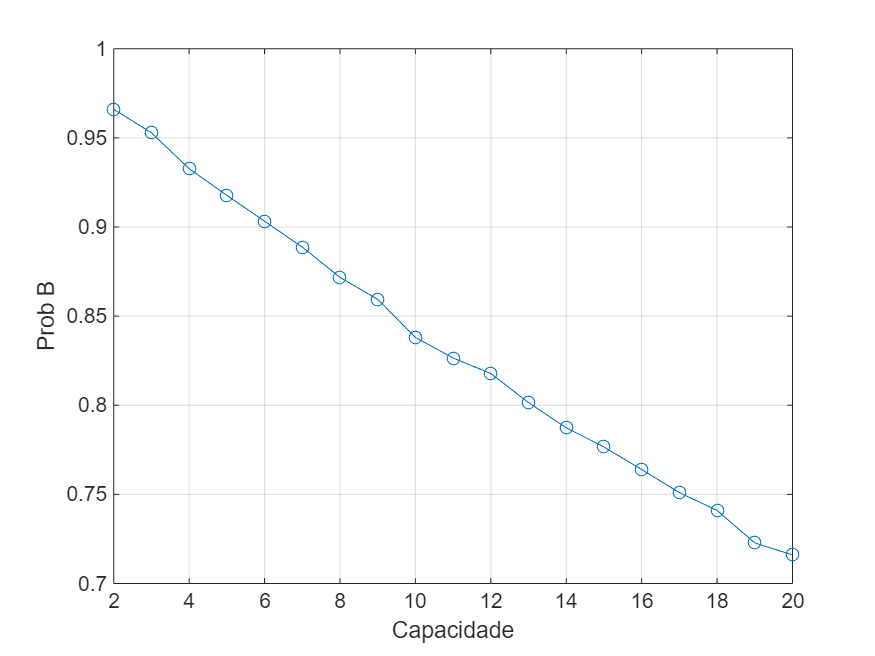

figure;
plot(nN,P,'-o');
xlabel("Capacidade");
ylabel("Prob B");
grid on; %6 brinquedos